clear all
close all
clc

load('Data_score.mat');  
N = 59; 
nameVariables = {'100m' ; 'longueur' ; 'poids' ; ...
'hauteur' ; '400m' ; '110m' ; 'disque' ; ...
'perche' ; 'javelot' ; '1500m' ; 'score'};
 [scoreClassed,I] = sort(Data(:,end), 1, 'descend');

 Y = Data(I,:); % tableau trié
 
 % 17 mauvais au 1500m, 8 et 15 mauvais à la perche
 % Sont le 53, 58 et 59 dans Y 
indexNotSelected = [53 58 59];
indexSelectedPoints = setdiff(1:59, indexNotSelected); 
%Y = Y( indexSelectedPoints, :); 


%% Analyse descriptive des données
% données centrées
g = Y'*ones(N,1) / N;
%A = mean(Y, 1);
X_Centered = Y - ones(N,1) * g.'; 
%X_Centered = Y - A; 
% Covariance
D_W = eye(N)*(1/N);
X_Cov = X_Centered' * D_W * X_Centered; 

% Corrélation
x_var = var(Y, 1);
D_sigma = diag(1./sqrt(x_var));

X_Cor = D_sigma * X_Cov * D_sigma; 

% tableau centré réduit
X_Normalized = X_Centered*D_sigma; 


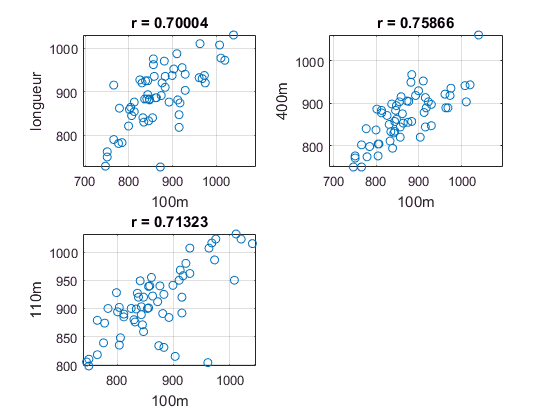

%% représentation de la corrélation
plot_SignificantCorrelation(X_Cor, 0.7, Y, nameVariables, I, 1)

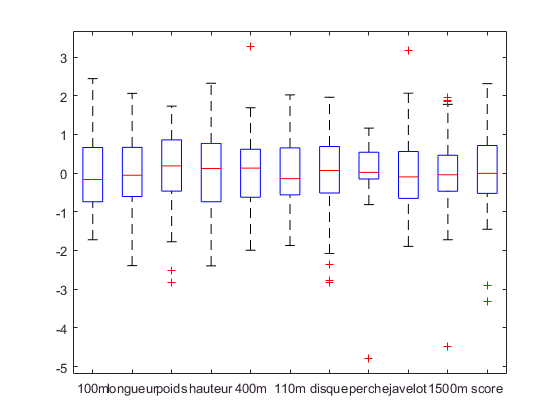

figure(3)
boxplot(X_Normalized, nameVariables)

%% ACP
indexDeletedColumn =1:10; % on enlève la colonne score
X_Centered = X_Centered(:,indexDeletedColumn); 
X_Normalized = X_Normalized(:,indexDeletedColumn);
X_Cor = X_Cor(indexDeletedColumn,indexDeletedColumn); 
Y = Y(:, indexDeletedColumn); 
x_var = var(Y, 1);

% vecteur propres et val propres
[L,B] = eig(X_Cor);
lambda = diag(B);
[lambda, index] = sort(lambda,1,'descend');
V = L(:,index);


% %normalisation (pas besoin  car on travaille avec X tilde)
%M = eye(10); 
% beta = ones(1, 10);
% axes_princip = V; 
% for i=1:10
%     beta(i) = sqrt(x_var(i)/(V(:,i)'*V(:,i)));
%     axes_princip(:,i) = V(:,i)*beta(i); % axes principaux
%     M(:, i) = M(:, i)*(1/x_var(i)); 
%     %(1/x_var(i))*(V(:,i)'*V(:,i)) % verification = 1
% end
% 
% % facteurs principaux
% F=M*axes_princip; 

%V'*M*V;  % = Id (ppté des axes principaux)

% composantes principales
C = X_Normalized*V

C =    -3.2156    2.8244    0.4941   -0.0812   -0.2508    0.6200   -0.1824   -0.1078    0.5740   -0.1287
   -4.9862   -1.0251    0.7545   -0.6276    0.7897    0.4536    0.1216   -0.1924   -0.5250   -0.0281
   -2.3190    1.7178    0.0802    0.0338   -0.6835   -0.1158   -0.5579    0.2779   -0.1838    0.0235
   -3.2837   -0.1963    0.4198    0.2310   -0.4761    0.3646   -0.6275   -0.1714    0.2351    0.4107
   -0.3849    2.3510    0.7997   -3.1745    0.3185    0.3543   -0.1639   -1.1463   -0.2535   -0.0935
   -0.5096    2.2084   -1.8337   -0.5824   -0.5963   -0.8286    0.4630    0.0595    0.4182    0.3818
   -1.9685    1.1970    1.3129    1.1930   -0.6117    0.0079   -0.6926   -0.8098    0.4941   -0.0137
   -2.0780    0.9508    1.9576    0.9880   -0.1738   -0.0276   -0.0457   -0.2811    0.1182   -0.0194
   -1.4504    0.1523   -1.0420   -0.7572    0.1348   -0.6034    0.3140   -0.5027   -0.3370   -0.2102
   -2.7841   -0.0429    0.4441    0.6828   -0.8536    0.6358   -0.8409    1.0999    0.4

% Vérification 
sum(lambda) % =10

ans = 10.0000

C(:, 1)'*D_W*C(:, 1) % =lambda1 normalement 

ans = 3.2875

C(:, 1)'*D_W*C(:, 2) % =0 normalement 

ans = 6.1062e-16

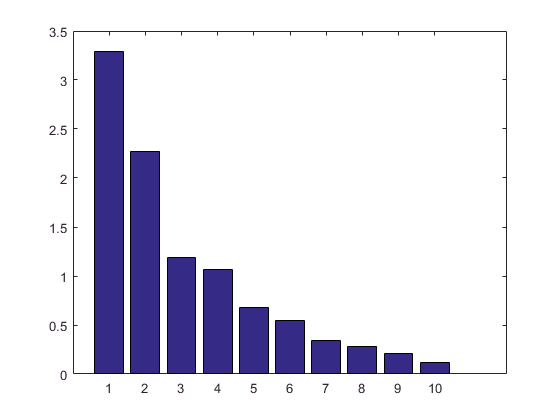

% Représentation des valeurs propres
bar(lambda) % diagramme de coude ou critère de Kaiser (vp>1)

Q = B / 10  % qualité par axe

Q =     0.3287         0         0         0         0         0         0         0         0         0
         0    0.2274         0         0         0         0         0         0         0         0
         0         0    0.1189         0         0         0         0         0         0         0
         0         0         0    0.1068         0         0         0         0         0         0
         0         0         0         0    0.0681         0         0         0         0         0
         0         0         0         0         0    0.0548         0         0         0         0
         0         0         0         0         0         0    0.0119         0         0         0
         0         0         0         0         0         0         0    0.0208         0         0
         0         0         0         0         0         0         0         0    0.0339         0
         0         0         0         0         0         0         0         0       

Q_globale_1 = (3.2875 + 2.2740) / 10 

Q_globale_1 = 0.5562

Q_globale_2 = (3.2875 + 2.2740 + 1.1891 + 1.0683 )/ 10 

Q_globale_2 = 0.7819

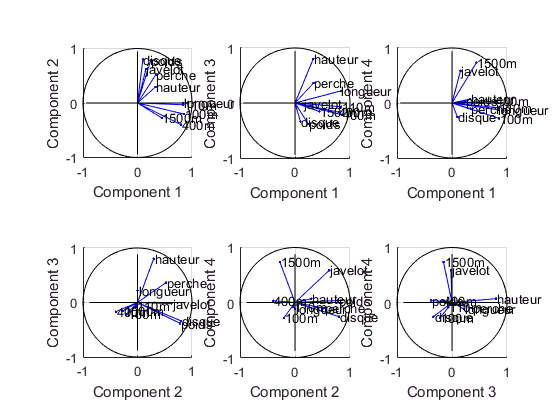

% cercle de corrélation (angle petit et distance proche du cercle unité)
correlationCircle=corr(X_Normalized,C);
%plot_CorrelationCircle(correlationCircle, nameVariables, 4, 4, 'additionalCorrCircle', correlationCircle, 'additionalVariableNames', nameVariables); 
plot_CorrelationCircle(correlationCircle, nameVariables(1:10), 4, 4); 

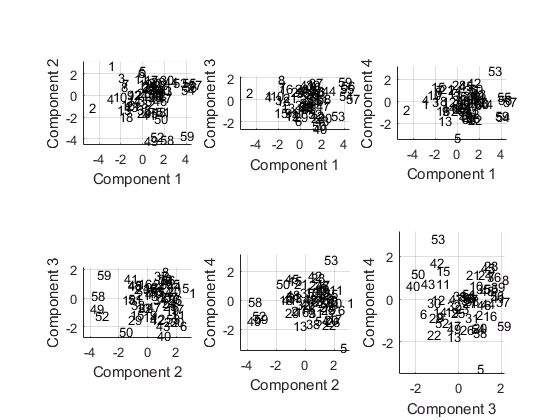

Q_var = correlationCircle^2; 
%plot_QualityVariable(Q_var, nameVariables(1:10), 4, 5);
plot_ProjectionObservation(C, indexSelectedPoints, 4, 6); 

%ctr = (1/N)*C'./lambda; 
%ctr > 2/N; 
%Q_ind = C.^2 ./ sum(C.^2, 2);
%plot_Quality(Q_ind(indexSelectedPoints, :), indexSelectedPoints, 0.5, 0.8, size(indexSelectedPoints, 2), 4, 7)
%plot_CorrelationCircle_QualityObservation(correlationCircle, nameVariables(1:10), Q_ind(indexSelectedPoints, :), C(indexSelectedPoints, :), indexSelectedPoints, 4, 8)

%% Graphes avec individus supplémentaires
%plot_ProjectionObservation(C(indexSelectedPoints, :), indexSelectedPoints, 4, 9, C(indexNotSelected, :), indexNotSelected)
%plot_Quality(Q_ind(indexSelectedPoints, :), indexSelectedPoints, 0.5, 0.8, N, 4, 9, Q_ind(indexNotSelected, :), indexNotSelected)
%plot_CorrelationCircle_QualityObservation(correlationCircle, nameVariables(1:10), Q_ind(indexSelectedPoints, :), C(indexSelectedPoints, :), indexSelectedPoints, 4, 8, Q_ind(indexNotSelected, :), C(indexNotSelected, :), indexNotSelected)
% Nouveaux individus 
% new_var = load('additionalVariables.mat').additionalVariables; 
% Damian Warner 2015 5 , 2017 28, 2019 46
% Kevin Mayer 2017 36, 2018 43
% Pierce LePage 2019 48
% https://www.ledevoir.com/sports/622785/decathlon-les-decathloniens-ces-meilleurs-athletes-inconnus-au-monde
% Choisir score au hasard?

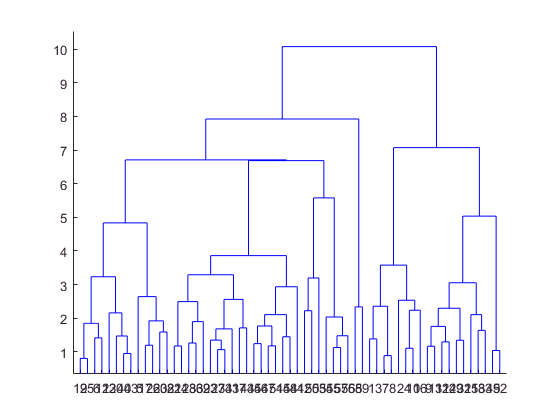

%% Classification

Z = linkage(X_Normalized, 'ward'); % avec données centrées réduites
Z(:,3) = Z(:,3) / sqrt(2);
figure;
% D = dendrogram(Z, 0, 'ColorThreshold', 'default');
D = dendrogram(Z, 0); 

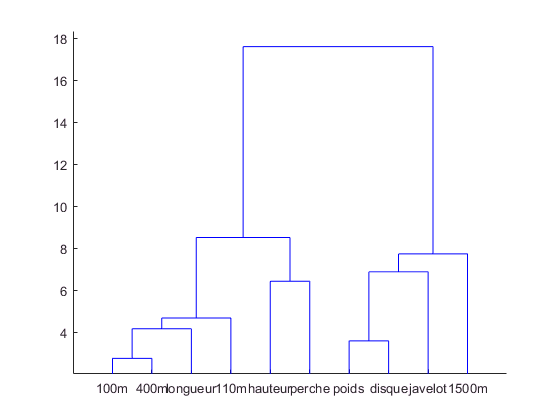

%% Classification des épreuves
%% Analyse descriptive des données
% données centrées
N = 10;
g = Y*ones(N,1) / N;
%A = mean(Y, 1);
X_Centered = Y' - ones(N,1) * g.'; 
%X_Centered = Y - A; 
% Covariance
D_W = eye(N)*(1/N);
X_Cov = X_Centered' * D_W * X_Centered; 

% Corrélation
x_var = var(Y', 1);
D_sigma = diag(1./sqrt(x_var));

X_Cor = D_sigma * X_Cov * D_sigma;

% tableau centré réduit
X_Normalized = X_Centered*D_sigma; 

%Classification des épreuves

Z = linkage(X_Normalized, 'ward'); % avec données centrées réduites
Z(:,3) = Z(:,3) / sqrt(2);
figure;
% D = dendrogram(Z, 0, 'ColorThreshold', 'default');
D = dendrogram(Z, 0, 'Labels', nameVariables(1:10)); 